# 路面不平度功率谱密度

clc
clear
close all

## 白噪声功率谱密度计算

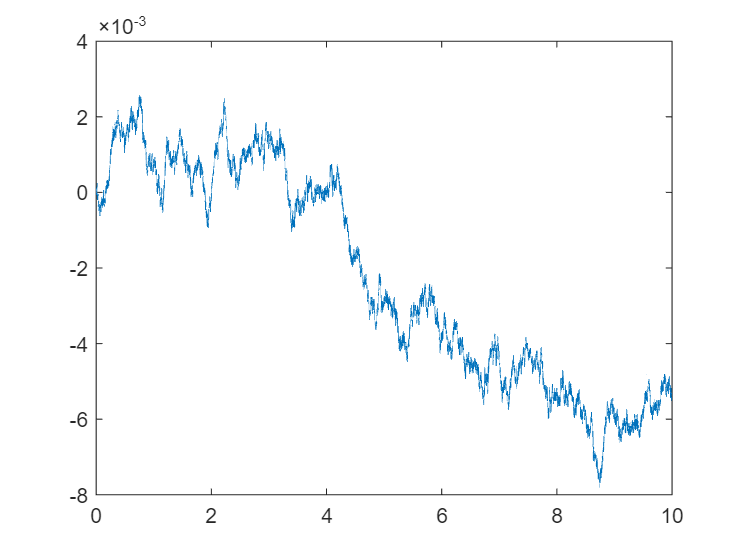

% P1_road_roughness
P2_road_roughness

% P3_road_roughness


% 计算功率谱密度
x       = roud_roughness;   % 路面激励的时域信号
fs      = 1/sample_time;    % 采样频率(应该等于噪声采样频率)

nfft    = 2^nextpow2(round(length(x)/4));
window  = hanning(nfft);
overlap = nfft/2;

[pxx,f] = pwelch(x,window,overlap,nfft,fs);

% 绘制功率谱密度
n=f/v;

loglog(n,pxx);
xlabel('频率 (Hz)');
ylabel('功率谱密度 (dB/Hz)');
title('信号功率谱密度图');

## 与标准功率谱密度比较

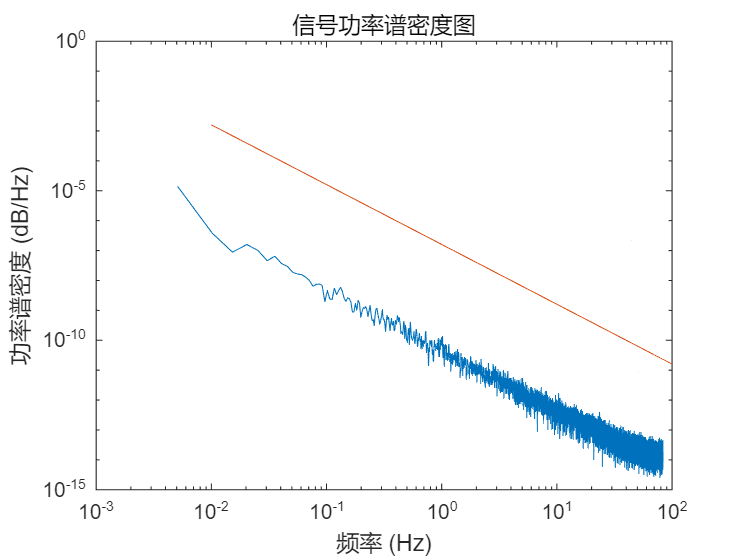

hold on

w    = 2;
n    = linspace(0.01,100,100);
Gqn  = Gqn0*(n/n0).^(-w);

loglog(n,Gqn)